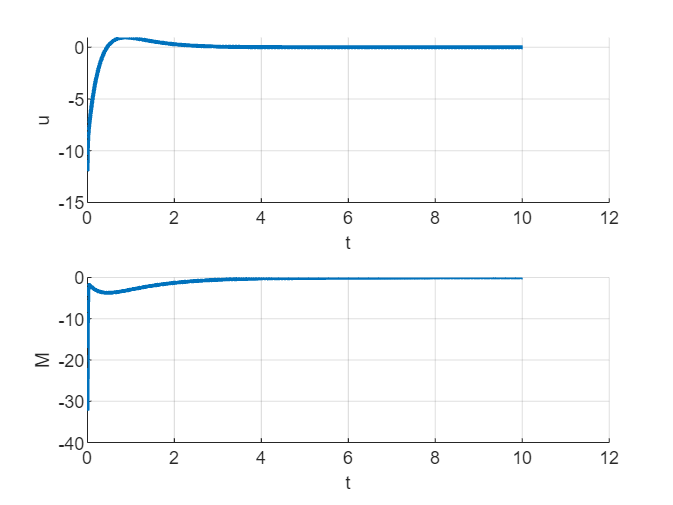

%% 参数设置
close all,clear,clc,
tic,

global m1 m2 l g
m1 = 1;
m2 = 1;
l = 1;
g = 9.8;

x = 1;
theta = deg2rad(35);
v = 0.2;
omega = deg2rad(2);

state = [x;theta;v;omega];
stateout = state;

t0 = 0.0;
dt = 0.01;
tf = 10;
tout = t0:dt:tf;
uout = [];  Mout = [];

kp1 = 10;   kd1 = 10;
kp2 = 50;   kd2 = 50;

%% 仿真
for t = t0:dt:tf
    u = -kp1*x - kd1*v;
    M = -kp2*theta - kd2*omega;
    uout = [uout,u];
    Mout = [Mout,M];

    ke1 = stateequation(t, state, u, M);
    ke2 = stateequation(t+0.5*dt, state+0.5*ke1*dt, u, M);
    ke3 = stateequation(t+0.5*dt, state+0.5*ke2*dt, u, M);
    ke4 = stateequation(t+dt, state+ke3*dt, u, M);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];

    x = state(1);
    theta = state(2);
    v = state(3);
    omega = state(4);
end

xout = stateout(1, :);
thetaout = stateout(2, :);
vout = stateout(3, :);
omegaout = stateout(4, :);

uout = [uout,uout(end)];
Mout = [Mout,Mout(end)];
tout = [tout,tout(end)+dt];
%% 绘图
figure(1);
subplot(2, 1, 1);
hold on;grid on;
plot(tout, uout, 'LineWidth', 2);
xlabel('t');ylabel('u');

subplot(2, 1, 2);
hold on;grid on;
plot(tout, Mout, 'LineWidth', 2);
xlabel('t');ylabel('M');

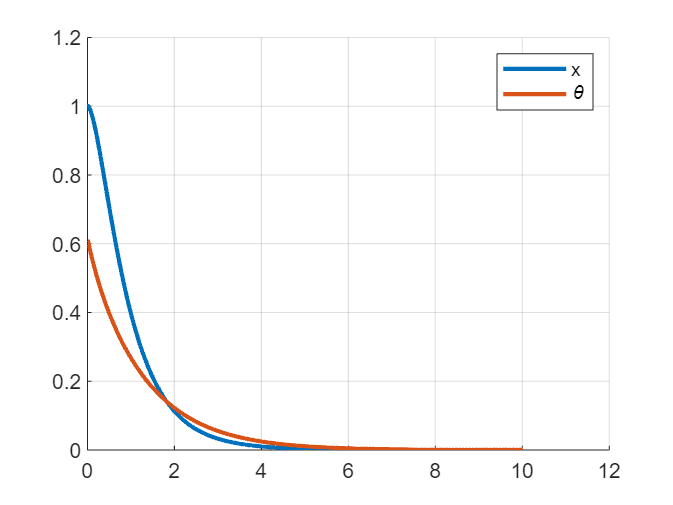


figure(2);
hold on;grid on;
plot(tout, xout, 'LineWidth', 2);
plot(tout, thetaout, 'LineWidth', 2);
legend("x","\theta");


%% 函数 

function statedot=stateequation(t, state, u, M)
global m1 m2 l g
% state = [x;theta;v;omega]
x     = state(1);
theta = state(2);
v     = state(3);
omega = state(4);

xdot = v;
thetadot = omega;
vdot = (m2*g*cos(theta)*sin(theta) - m2*l*omega^2*sin(theta))/(m1 + m2*sin(theta)^2) + ...
       u/(m1 + m2*sin(theta)^2) + cos(theta)*M/(m1 + m2*sin(theta)^2)/l;
omegadot = ((m1 + m2)*g*sin(theta) - m2*l*omega^2*cos(theta)*sin(theta))/(m1 + m2*sin(theta)^2)/l + ...
            u*cos(theta)/(m1 + m2*sin(theta)^2)/l + (m1 + m2)*M/(m1 + m2*sin(theta)^2)/m2/l^2;

statedot = [xdot;thetadot;vdot;omegadot];
end